# Preamble

clc, clear;

## Includes

addpath("../auxiliary/");

## Define the problem parameters

% Amplitude at the beam's ends
w0 = 0;

%material
propStruct.E = 1e7;
propStruct.v = 0.3;
propStruct.p = 7750*1e1; %kg/m3 (steel)
propStruct.g = 9.81; %(m/s2)

% Computational domain
propGeom.X0 = 0;
propGeom.XL = 1;
XComp = [propGeom.X0 propGeom.XL];

propGeom.Y0=0;
propGeom.YL=0.25;
YComp = [propGeom.Y0 propGeom.YL];

## Generate the training data

% points over which to enforce the boundary conditions by means of the loss
% of the neural network
numBC = 32;

% boundary conditions
% W(x=0 , y) = 0
X0BC = propGeom.X0 * ones(1,numBC);
Y0BC = linspace(propGeom.Y0, propGeom.YL , numBC);
U0BC = w0*ones(2, numBC);

## Create some random points between the computational interval

numInternColl = 2*128;
pointSet = sobolset(2);
points = net(pointSet,numInternColl);
X = (XComp(1, 1) + points(:, 1)*(XComp(1, 2) - XComp(1, 1)))';
Y = (YComp(1, 1) + points(:, 2)*(YComp(1, 2) - YComp(1, 1)))';


% %% Deep learning model

% % Number of layers and Number of neurons per layer
numLayers = 5;
numNeurons = 15;

%%Create parameters as a struct
parameters = struct;

sz = [numNeurons 2];

% % initialize the weights and biases for the first fully connected operation
% The input layer has 2 neurons and numNeurons connections to the next layer
 parameters.fc1_Weights = initializeHe(sz, 2, "double");
 parameters.fc1_Bias = initializeZeros([numNeurons 1],"double");

% % Initialize the weights and biases for the hidden fully connected operations.
for layerNumber = 2:numLayers-1
    name = "fc"+layerNumber;

    sz = [numNeurons numNeurons];
    parameters.(name+"_Weights") = initializeHe(sz, numNeurons, "double");
    parameters.(name+"_Bias") = initializeZeros([numNeurons 1], "double");
end
 
% % Initialize the final fully connected operation. The output layer has 2 
% %  neurons and returns the predicted solution u(x,y) and w(x,y)
sz = [2 numNeurons];
parameters.("fc" + numLayers +"_Weights") = initializeHe(sz, numNeurons, "double");
parameters.("fc" + numLayers + "_Bias") = initializeZeros([2 1],"double");

## Test the initialized network

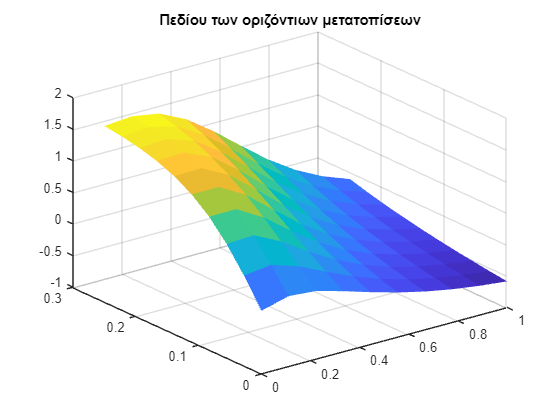

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parameters, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")
title("Πεδίου των οριζόντιων μετατοπίσεων")

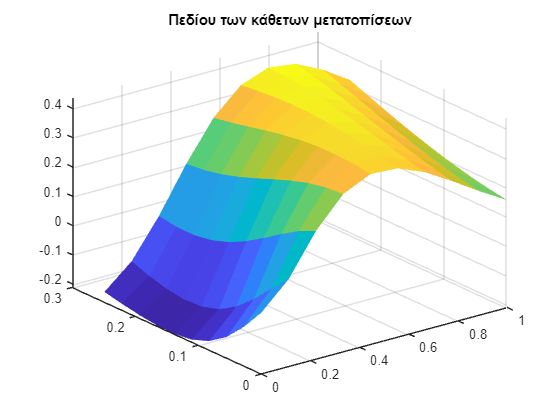

figure
surf(Xvct, Yvct, dispY, "LineStyle","none")
title("Πεδίου των κάθετων μετατοπίσεων")

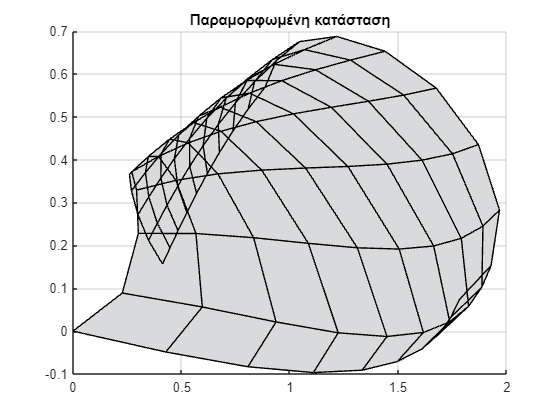

figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);
view(2)
title("Παραμορφωμένη κατάσταση")

## Train the physics-informed neural network

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Specify the optimization options
opts = optimoptions('fmincon', ... % fminunc
    'HessianApproximation', 'lbfgs', ...
    'MaxIterations', 1000 , ... % 7500
    'MaxFunctionEvaluations', 1000, ... % 7500
    'OptimalityTolerance', 1e-12, ...
    'SpecifyObjectiveGradient', true, ...
    'UseParallel', false, ...
    'Display', 'iter');

% Learning properties
propLearning.alpha = 1e-9;
propLearning.beta = 1;

% %% Train the network using fmincon

% % extract data and names from the parameters
[parametersV_init,parameterNames,parameterSizes] = parameterStructToVector( ...
    parameters);
parametersV_init = extractdata(parametersV_init);

% % Convert the training data to dlarray objects with format 'CB' (channel, batch).
dlX = dlarray(X,'CB');
dlY = dlarray(Y,'CB');
dlX0BC = dlarray(X0BC,'CB');
dlY0BC = dlarray(Y0BC,'CB');
dlU0BC = dlarray(U0BC,'CB');

%%Create a function handle with one input that defines the objective function.
objFun = @(parameters) objectiveFunction(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, ...
    parameterNames, parameterSizes, propStruct, propLearning);

% Update the learnable parameters using the fmincon function
parametersConv = fmincon(objFun, parametersV_init, [], [], [], [], [], [], [], ...
    opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.550270e+07    0.000e+00    5.430e+07
    1       6    5.590311e+06    0.000e+00    3.363e+07    2.823e+01
    2       7    1.955417e+04    0.000e+00    1.317e+05    7.534e+00
    3       8    5.639928e+03    0.000e+00    3.403e+04    4.460e-02
    4       9    3.632040e+03    0.000e+00    2.131e+04    1.648e-02
    5      10    1.656198e+03    0.000e+00    9.571e+03    2.951e-02
    6      11    7.904036e+02    0.000e+00    4.736e+03    2.682e-02
    7      12    3.187711e+02    0.000e+00    2.130e+03    2.982e-02
    8      13    1.157323e+02    0.000e+00    9.235e+02    2.795e-02
    9      14    3.994907e+01    0.000e+00    3.732e+02    2.404e-02
   10      15    1.903566e+01    0.000e+00    1.322e+02    1.702e-02
   11      16    1.516277e+01    0.000e+00    7.228e+01    9.403e-03
   12      17    1.445429e+01    0.000e+00    6

% parametersVConv = fminunc(objFun, parametersV, opts);

% % For prediction convert the vector of parameters to a structure
parametersConv = parameterVectorToStruct(parametersConv, ...
    parameterNames, parameterSizes);

% % Export network into dat file for future use
% save ('2D_Beam.mat', 'parameters');
% 
% %% Auxiliary functions
%

## Test the converged network

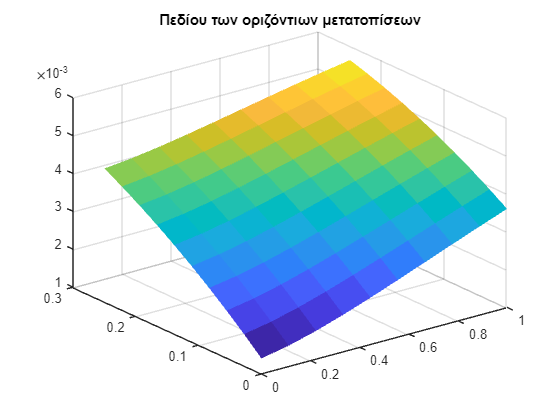

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parametersConv, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")
title("Πεδίου των οριζόντιων μετατοπίσεων")

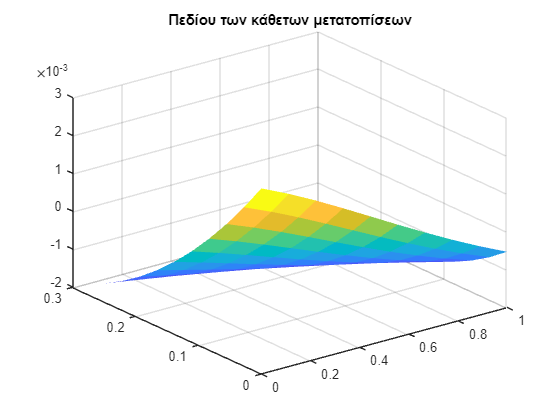

figure
surf(Xvct, Yvct, dispY, "LineStyle","none")
title("Πεδίου των κάθετων μετατοπίσεων")

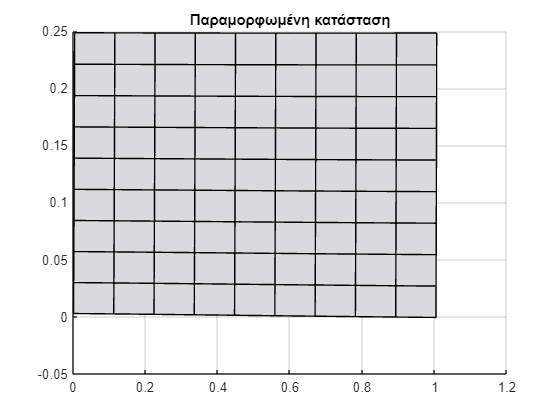

figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);
view(2)
title("Παραμορφωμένη κατάσταση")

## Define the objective function that optimizes for the weights and biases

function [loss, gradientsV] = objectiveFunction ...
    (parametersV, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, parameterNames, parameterSizes, propStruct, propLearning)

    % Convert parameters to structure of dlarray objects
    parametersV = dlarray(parametersV);
    parameters = parameterVectorToStruct(parametersV, parameterNames, ...
        parameterSizes);
    % 
    % Evaluate model gradients and loss
    [gradients, loss] = dlfeval(@modelGradients, parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, ...
        propStruct, propLearning);    
    % Return loss and gradients for fmincon
    gradientsV = parameterStructToVector(gradients);
    gradientsV = extractdata(gradientsV);
    loss = extractdata(loss);
end

## Function that returns the loss and its gradient with respect to the weights and biases

function [gradients,loss] = modelGradients(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, propStruct, propLearning)
        % Make predictions with the initial conditions
    dlU = model(parameters, dlX, dlY);

$\frac{\partial u_x}{ \partial X}$, $\frac{\partial u_y}{ \partial Y}$, $\frac{\partial u_x}{ \partial Y}$, $\frac{\partial u_y}{ \partial X}$

    d_dlUX_dx = dlgradient(sum(dlU(1, :),'all'), dlX, 'EnableHigherDerivatives', true);
    d_dlUY_dy = dlgradient(sum(dlU(2, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUX_dy = dlgradient(sum(dlU(1, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUY_dx = dlgradient(sum(dlU(2, :),'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial^2 X}$, $\frac{\partial^2 u_y}{ \partial^2 Y}$, $\frac{\partial^2 u_x}{ \partial^2 Y}$, $\frac{\partial^2 u_y}{ \partial^2 X}$

    dd_dlUX_dxdx = dlgradient(sum(d_dlUX_dx, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dydy = dlgradient(sum(d_dlUY_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydy = dlgradient(sum(d_dlUX_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdx = dlgradient(sum(d_dlUY_dx, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial X \partial Y}$, $\frac{\partial^2 u_x}{ \partial Y \partial X}$,   $\frac{\partial^2 u_y}{ \partial X \partial Y}$, $\frac{\partial^2 u_y}{ \partial Y \partial X}$

    dd_dlUX_dxdy = dlgradient(sum(d_dlUX_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydx = dlgradient(sum(d_dlUX_dy, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdy = dlgradient(sum(d_dlUY_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dydx = dlgradient(sum(d_dlUY_dy, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial \sigma _{xx}}{ \partial X}$, $\frac{\partial \sigma _{yy}}{ \partial Y}$, $\frac{\partial \sigma _{xy}}{ \partial Y}$, $\frac{\partial \sigma _{yx}}{ \partial X}$

    d_Sxx_dx = (propStruct.E/(1-propStruct.v^2))*(dd_dlUX_dxdx + propStruct.v*dd_dlUY_dydx);
    d_Syy_dy = (propStruct.E/(1-propStruct.v^2))*(propStruct.v*dd_dlUX_dxdy + dd_dlUY_dydy);
    
    d_Sxy_dy = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydy + dd_dlUY_dxdy);
    d_Syx_dx = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydx + dd_dlUY_dxdx);


$$f=\textrm{div}\sigma +b$$


    divStress = [d_Sxx_dx + d_Sxy_dy; d_Syy_dy + d_Syx_dx];
    b_const = - propStruct.p*propStruct.g;
    b = zeros(2, length(dlX));
    b = dlarray(b, 'CB');
    b(2, :) = b_const;

    % equilibrium eq.
    f = divStress + b;
%     f = divStress;
    
    %surf here!!!
    %loss f
    zeroTarget = zeros(size(f), 'like', f);
    lossF = mse(f, zeroTarget);


    % Compute the system response at the beam's left edge
    dlUBC = model(parameters, dlX0BC, dlY0BC);
%     lossU = mse(dlUBC, dlarray(zeros(2,32), 'CB'));
    lossU = mse(dlUBC, dlU0BC);
  

    % Total loss
    loss = propLearning.alpha*lossF + propLearning.beta*lossU;


$$$$


% Calculate gradients with respect to the learnable parameters.
    gradients = dlgradient(loss, parameters);
end

## Feed-forward (model) function for the neural network

function dlU = model(parameters, X, Y)

    dlXY = [X; Y];
    numLayers = numel(fieldnames(parameters))/2;
    
    % First fully connect operation.
    weights = parameters.fc1_Weights;
    bias = parameters.fc1_Bias;
    dlU = fullyconnect(dlXY,weights,bias);
    
%     % tanh and fully connect operations for remaining layers.
    for i = 2:numLayers
        name = "fc" + i;
    
        dlU = tanh(dlU);
    
        weights = parameters.(name + "_Weights");
        bias = parameters.(name + "_Bias");
        dlU = fullyconnect(dlU, weights, bias);
    end
    
end